clear all
% z t r
date = 230116;
shot_num = 18;
low_n_folder = strcat('C:\Users\uswk0\OneDrive\ドキュメント\GitHub\test-open\道家\卒論\data\',num2str(date),'/');
calib_coefficient = zeros(1,24);
direction = ...
   [1,1,1,1,1,1,...
    -1,1,1,-1,1,1,...
    1,1,1,-1,1,1,...
    1,1,1,1,1,1];
for i = 1:8
    calib_coefficient((i-1)*3+1:(i-1)*3+3) = [37.7,41.6,133]*10^-6;
end
% Get all csv files in the current folder
files = dir(strcat(low_n_folder,'*.csv'));
% Loop through each
for id = 1:length(files)
    % Get the file name (minus the extension)
    [path,name,~] = fileparts(files(id).name);
    low_n_name = strcat(low_n_folder,name);
    %disp(low_n_name);
    o_index = strfind(low_n_name, 'o');
    current_shot = str2double(low_n_name(o_index(end)+1:end));
    if (shot_num == current_shot)
        toroidal_mode_raw = readmatrix(low_n_name);
        break
    end
end
if ~exist('toroidal_mode_raw','var')
    disp(['shot ',num2str(shot_num),' does not exist!'])
    return
end



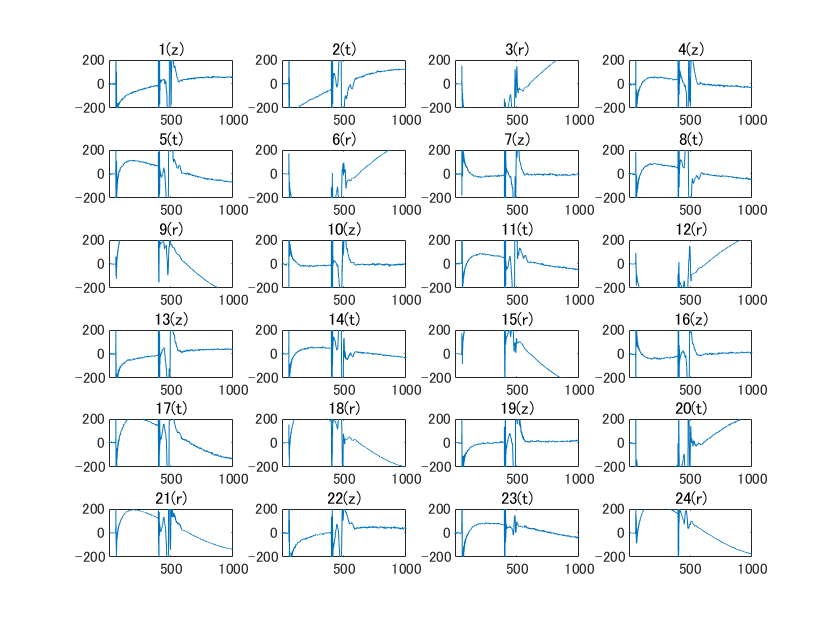

% rearrange to 1-24 in channel number according to labels on cable
toroidal_mode_B = toroidal_mode_raw(:,2:25)./calib_coefficient.*direction;

% integration
int_toroidal_mode_B = trapz(toroidal_mode_B);

%toroidal_mode_B = toroidal_mode_raw(:,2:25)*1000;
time_array = toroidal_mode_raw(:,1);
clearvars -except toroidal_mode_B time_array date shot_num t_start t_end...
    y_upperlim y_lowerlim calib_coefficient
% plotting setting
t_start = 1;
t_end = 1000;
y_upperlim = 200;
y_lowerlim = -200;
figure
for i = 1:24
    subplot(6,4,i)
    plot(time_array,smooth(toroidal_mode_B(:,i),0.004));
    xlim([t_start t_end])
    ylim([y_lowerlim y_upperlim])
    component_all = ['r','z','t'];
    component = component_all(rem(i,3)+1);
    title([num2str(i),'(',component,')'])
end

btで計算

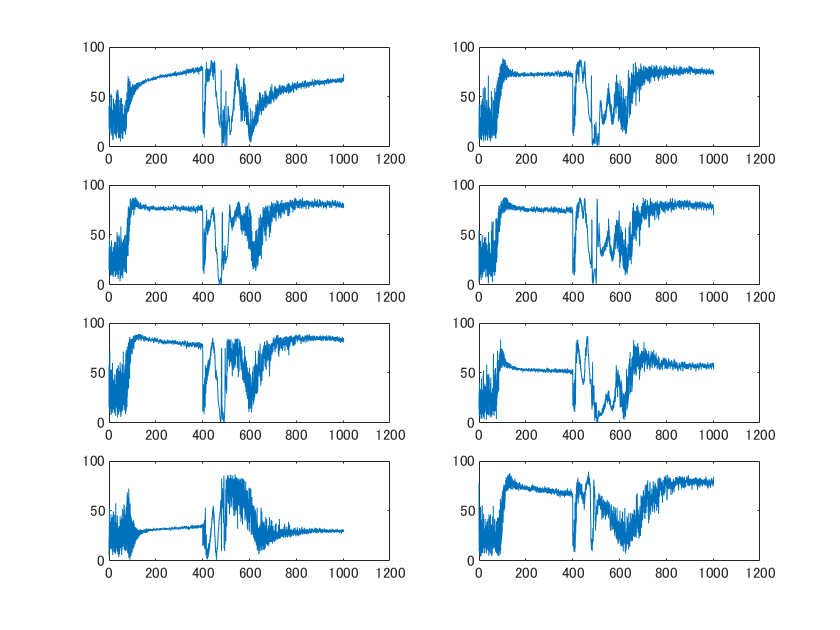

%Vbt = bt*cos(theta);
%Vbr = bt*sin(theta);
%theta = atan2(Vbr/Vbt);
theta = zeros(length(time_array),8);
for i = 1:8
 theta(:,i) = abs(atan(toroidal_mode_B(:,i*3)./toroidal_mode_B(:,i*3-1))*180/pi());

 subplot(4,2,i)
 plot(time_array, smooth(theta(:,i)));
end

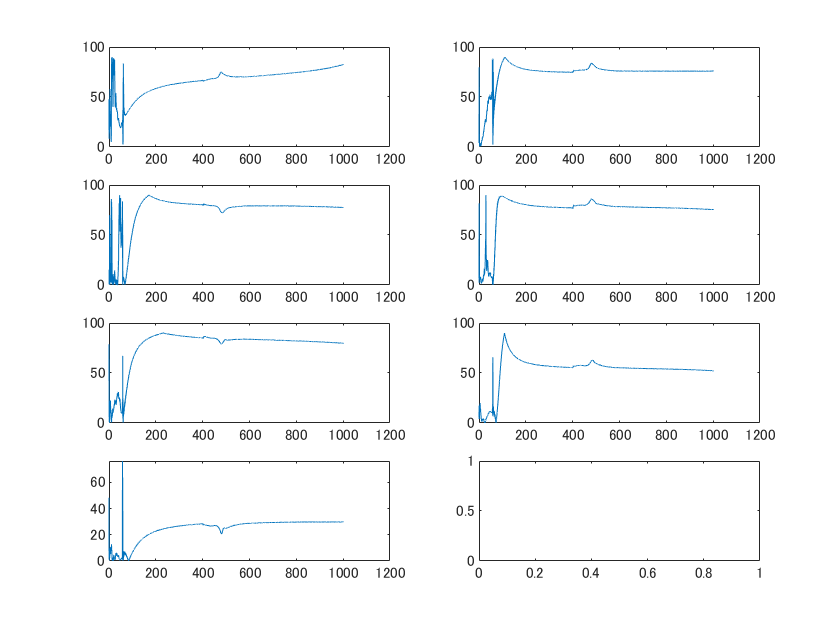

Index in position 2 exceeds array bounds. Index must not exceed 1.

%積分後信号のphase計算→平均とって較正

theta = zeros(length(time_array),8);
integrated_B = zeros(length(time_array),24);
ave_theta = zeros(1,8);
for i = 1:24
    integrated_B(:,i) = cumtrapz(toroidal_mode_B(:,i)*10^-7*1000*10*1000);
end

for i = 1:8
 theta(:,i) = abs(atan(integrated_B(:,i*3)./integrated_B(:,i*3-1))*180/pi());
 subplot(4,2,i);
 plot(time_array, theta(:,i));
 ave_theta(1,i) = mean(theta(6000:10000,i));
end

for i = 1:8
plot(time_array, average_theta(1,i)*ones(1,time_array));
end

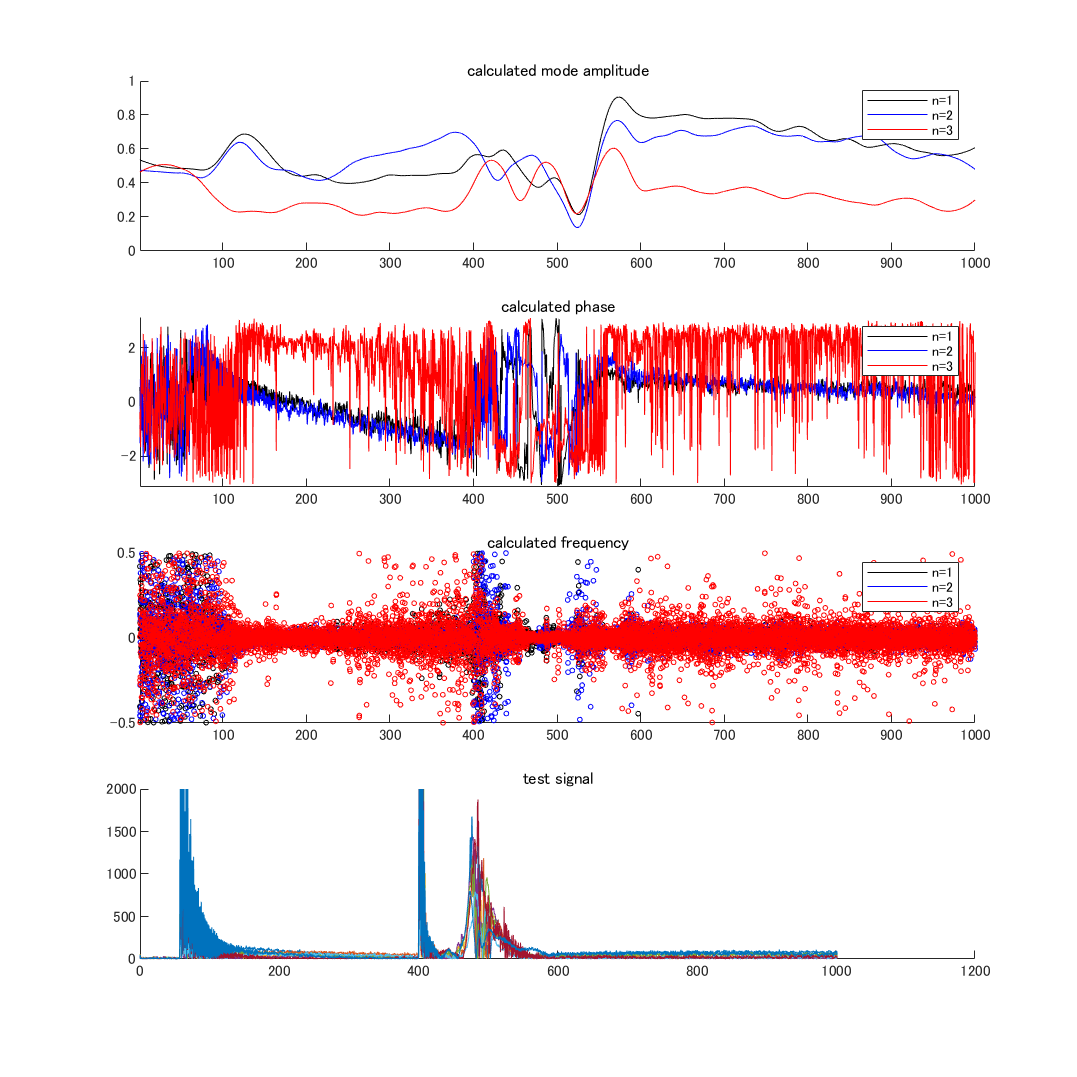



toroidal_mode_B_smoothed = toroidal_mode_B;
for i = 1:24
    toroidal_mode_B_smoothed(:,i) = smooth(toroidal_mode_B(:,i));
end
x = [0,4/24,7/24,9/24,12/24,15/24,17/24,20/24]; % non-uniform probe placement
%t = time_array(3500:6000);
t = time_array;
signal = toroidal_mode_B_smoothed(:,1:3:22);%Bzで計算
for i = 1:8
    index_bt = i*3-1;
    index_br = i*3;
    index_bz = i*3-2;
    %signal(:,i) = sqrt(toroidal_mode_B_smoothed(:,index_bt).^2+toroidal_mode_B_smoothed(:,index_br).^2);
    signal(:,i) = sqrt(toroidal_mode_B_smoothed(:,index_bz).^2+toroidal_mode_B_smoothed(:,index_bz).^2);
end
%signal = signal(3500:6000,:);
[n_Amp,n_Ph] = toroidal_mode(t,x,signal); % get amplitude and phase
% calculate frequency from phase (smoothed)
n1_Omega = calculate_omega(smooth(cumulative_phase(n_Ph(1,:)),0.1,'loess'));
n2_Omega = calculate_omega(smooth(cumulative_phase(n_Ph(2,:)),0.1,'loess'));
n3_Omega = calculate_omega(smooth(cumulative_phase(n_Ph(3,:)),0.1,'loess'));
% *************** plotting ***************
figure('Position', [0 0 800 800]);
subplot(4,4,1:4)
hold on
plot(t,smooth(n_Amp(2,:)./n_Amp(1,:),0.1,'loess'),'k');
plot(t,smooth(n_Amp(3,:)./n_Amp(1,:),0.1,'loess'),'b');
plot(t,smooth(n_Amp(4,:)./n_Amp(1,:),0.1,'loess'),'r');
%scatter(t,n_Amp(2,:)./n_Amp(1,:),6,'k');
%scatter(t,n_Amp(3,:)./n_Amp(1,:),6,'b');
%scatter(t,n_Amp(4,:)./n_Amp(1,:),6,'r');

%scatter(t,smooth(n_Amp(2,:)./n_Amp(1,:)),6,'k');
%scatter(t,smooth(n_Amp(3,:)./n_Amp(1,:)),6,'b');
%scatter(t,smooth(n_Amp(4,:)./n_Amp(1,:)),6,'r');
legend('n=1','n=2','n=3');
ylim([0 1])
xlim([t_start t_end])
title('calculated mode amplitude')
hold off
subplot(4,4,5:8)
hold on
%plot(t,n_Ph(1,:),'k');plot(t,n_Ph(2,:),'b');plot(t,n_Ph(3,:),'r');
plot(t,smooth(n_Ph(1,:)),'k');plot(t,smooth(n_Ph(2,:)),'b');plot(t,smooth(n_Ph(3,:)),'r');
ylim([-pi pi]);
xlim([t_start t_end])
legend('n=1','n=2','n=3');
title('calculated phase')
hold off
subplot(4,4,9:12)
hold on
plot(t,n1_Omega/(2*pi),'k');
plot(t,n2_Omega/(2*pi),'b');
plot(t,n3_Omega/(2*pi),'r');
scatter(t,calculate_omega(cumulative_phase(n_Ph(1,:)))/(2*pi),6,'k');
scatter(t,calculate_omega(cumulative_phase(n_Ph(2,:)))/(2*pi),6,'b');
scatter(t,calculate_omega(cumulative_phase(n_Ph(3,:)))/(2*pi),6,'r');
legend('n=1','n=2','n=3');
%ylim([-0.1 0.3]);
xlim([t_start t_end])
title('calculated frequency')
hold off
subplot(4,4,13:16)
hold on
for i = 1:8
    plot(t,signal(:,i));
    title('test signal')
end
%xlim([t_start t_end])
%ylim([y_lowerlim y_upperlim])
ylim([0 2000])
hold off

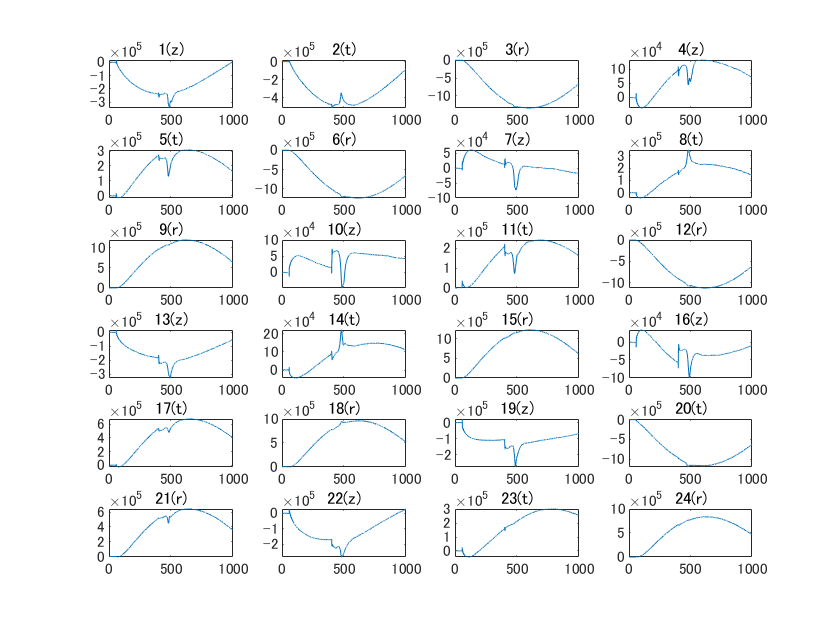

figure
for i = 1:24
    subplot(6,4,i)
    plot(time_array,cumtrapz(toroidal_mode_B(:,i))*10^-7*1000*10*1000);
    %xlim([t_start t_end])
    %ylim([-1 1])
    component_all = ['r','z','t'];
    component = component_all(rem(i,3)+1);
    title([num2str(i),'(',component,')'])
end

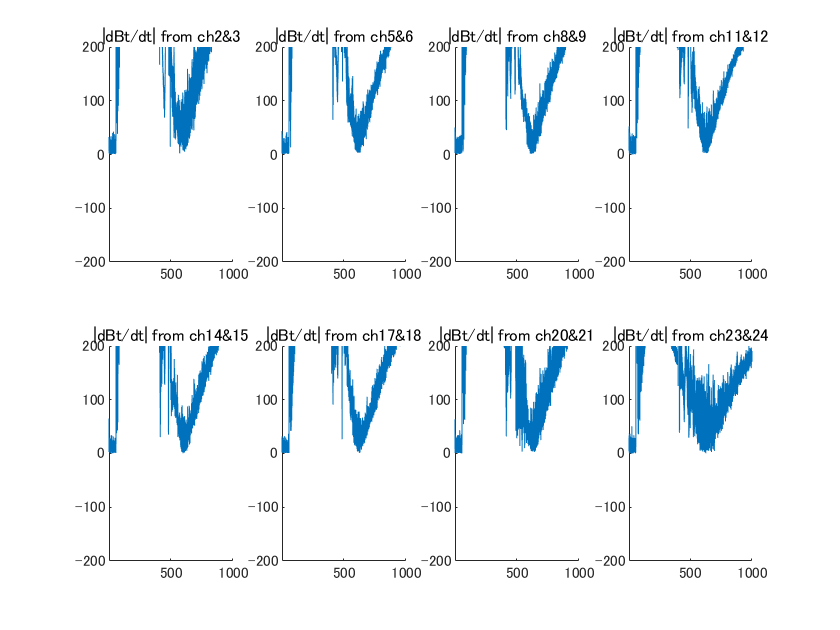

figure
for i = 1:8
    subplot(2,4,i)
    index_bz = i*3-2;
    index_bt = i*3-1;
    index_br = i*3;
    bt_abs = sqrt(toroidal_mode_B(:,index_bt).^2+toroidal_mode_B(:,index_br).^2);
    hold on
    plot(time_array,bt_abs);
    hold off
    xlim([t_start t_end])
    ylim([y_lowerlim y_upperlim])
    title(['|dBt/dt| from ch',num2str(index_bt),'&',num2str(index_br)])
end

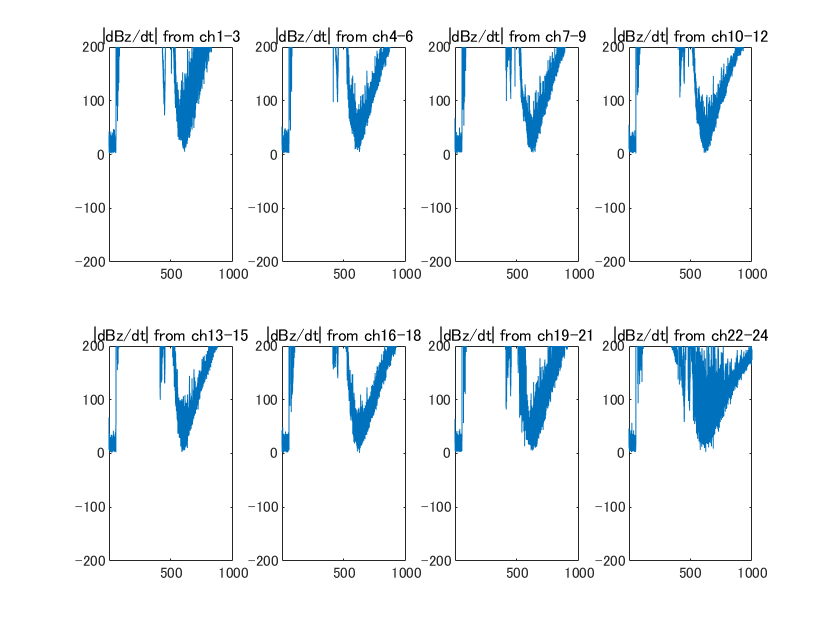

figure
for i = 1:8
    subplot(2,4,i)
    index_bz = i*3-2;
    index_bt = i*3-1;
    index_br = i*3;
    bp_abs = sqrt(toroidal_mode_B(:,index_bz).^2+toroidal_mode_B(:,index_br).^2+...
        toroidal_mode_B(:,index_bt).^2);
    plot(time_array,bp_abs);
    xlim([t_start t_end])
    ylim([y_lowerlim y_upperlim])
    title(['|dBz/dt| from ch',num2str(index_bz),'-',num2str(index_br)])
end